# Extracting point clouds

Using this MATLAB live script, you can interactively preprocess the data from your extraction points

### Extracting data from collection point

- rosGetRaw

- ros2GetRaw

- readCloudsPly

- preprocess_cloud

tic
pathname="C:\Users\agori\Documents\MATLAB\MSc\appDesign\ExtractPC\p3\";
[all_clouds, fnames] =rosGetRaw(pathname);

#### getMinSz: helps to determine number of point clouds to use by checking the minimum size of your data collection

[minsz, testout] = getMinSz(all_clouds,fnames);

             Filenames             NClouds
    ___________________________    _______

    {'2022-07-23-21-13-51.bag'}      321  
    {'2022-07-23-21-17-10.bag'}      225  
    {'2022-07-23-21-18-58.bag'}      295  
    {'2022-07-23-21-21-48.bag'}      234  
    {'2022-07-23-21-23-08.bag'}      206  
    {'2022-07-23-21-25-26.bag'}      178  
    {'2022-07-23-21-28-10.bag'}      100  
    {'2022-07-23-21-30-11.bag'}       80  
    {'2022-07-23-21-32-03.bag'}      159  

Min size=80


toc

Elapsed time is 19.999279 seconds.


### Cropping to the desired region of interest (ROI)

An approximate manual cropping assists in the 3D reconstruction process. Here you can edit z_roi, y_roi and x_roi and see how this impacts the display. Once you are happy with this, the **cropMerge **function can be run where you decide how many messages you want to concatenate and what your roi you want to crop.

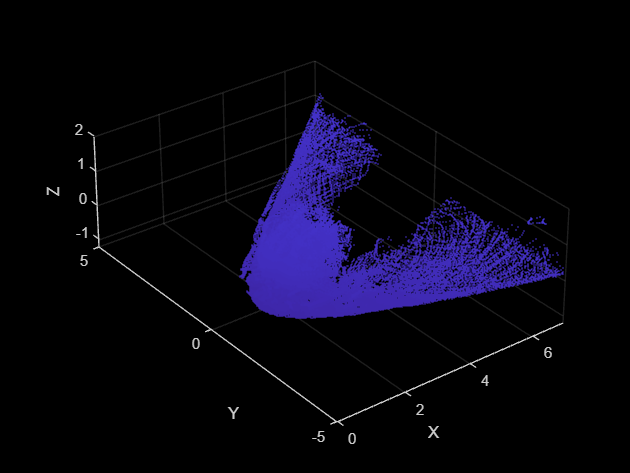

pcshow(testout,"AxesVisibility","on");
xlabel('X');
ylabel('Y');s
zlabel('Z');

z_roi=[-inf,2];
y_roi=[-5,5];
x_roi=[0,7];

roi=[x_roi,y_roi,z_roi];
zlim(z_roi);
ylim(y_roi);
xlim(x_roi);

### cropMerge

tic
[cat_pointCloudArray] = cropMerge(roi,50,all_clouds);
toc

Elapsed time is 9.078782 seconds.


## Displaying your final clouds

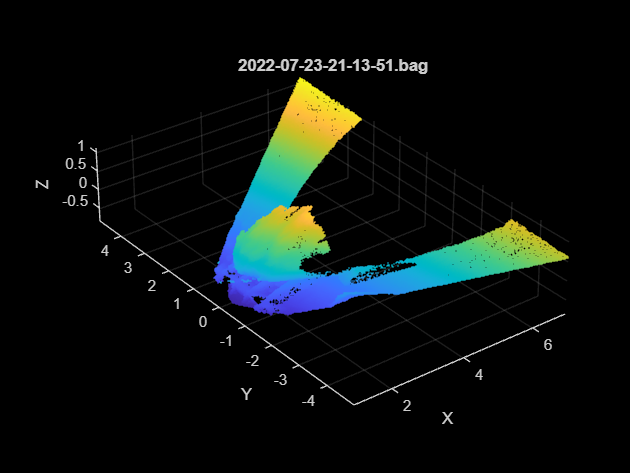

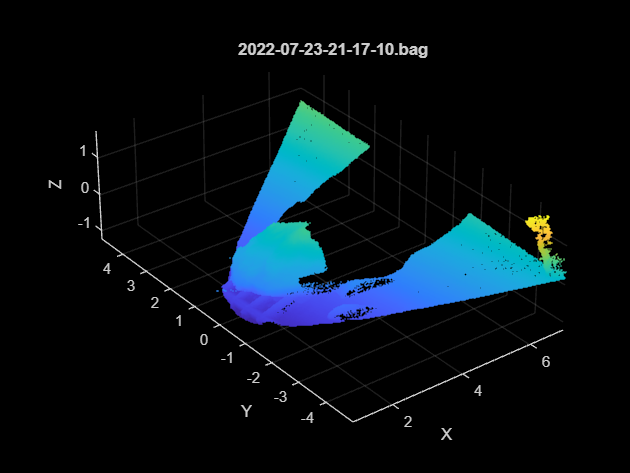

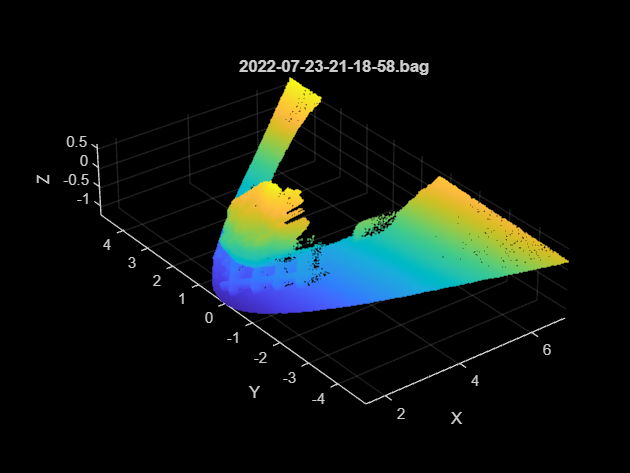

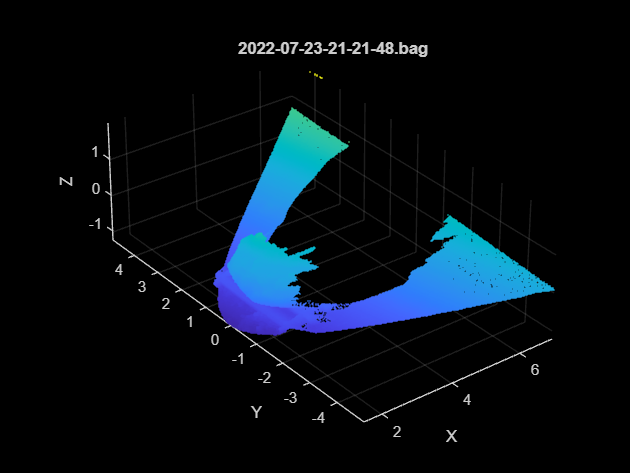

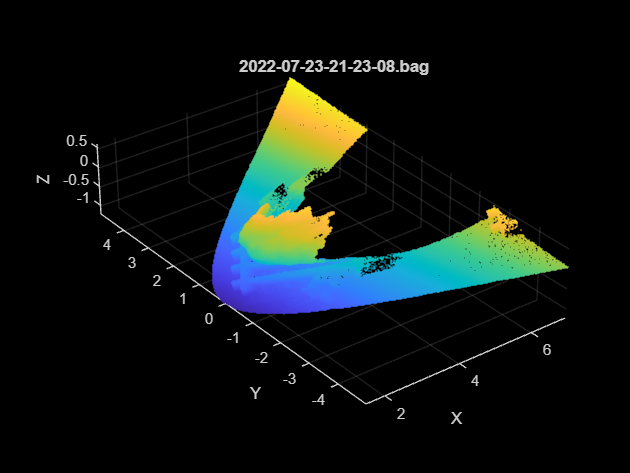

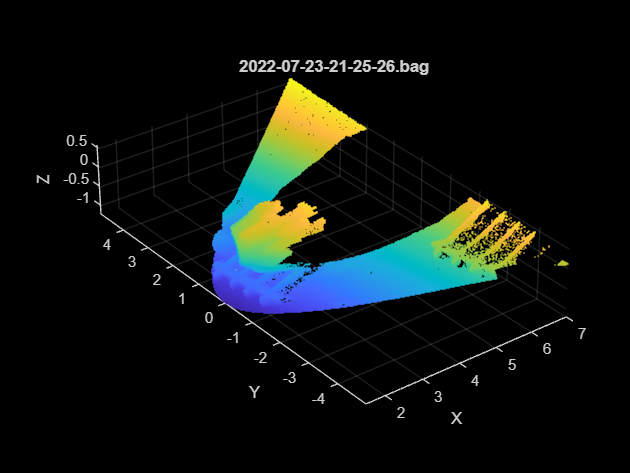

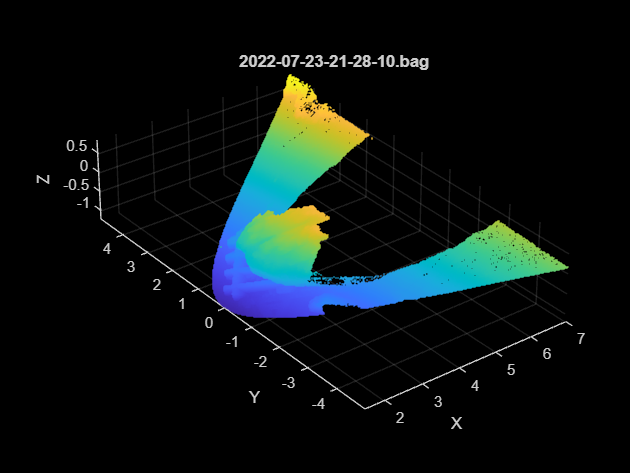

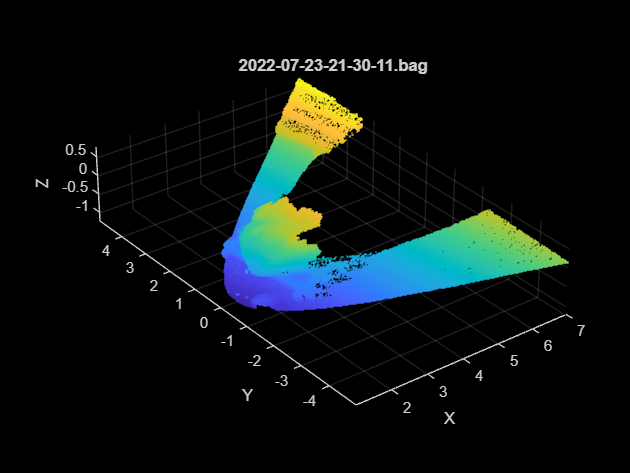

nviews=length(all_clouds);
for k=1:nviews
    figure
    pcshow(cat_pointCloudArray(k),"AxesVisibility","on")
    title(fnames(k))
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
end

## Saving the raw data for future use

save("Pancake3Data");